clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque.csv';
% network = '_seal_pred_filtered_torque_si_3_15.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

arm = 'psm3_fena';


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];
    


%       joint_path = ['../../../Downloads/trial_pipeline_1', '/joints/'];
%       jacobian_path = ['../../../Downloads/trial_pipeline_1', '/jacobian/'];
%       torque_path = ['../../../Downloads/trial_pipeline_1', '/TO_free_comp_model_pred.csv'];
%       corr_tq_path = ['../../../Downloads/trial_pipeline_1', '/filtered_corrected_torque_prediction.csv'];

      
      joint_path = ['../../exp_feb_21_tissue_train/test', '/joints/'];
      jacobian_path = ['../../exp_feb_21_tissue_train/test', '/jacobian/'];
      torque_path = ['../../exp_feb_21_tissue_train/test', '/lstm_seal_pred_filtered_torque.csv'];

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
jacobian_data = readmatrix([jacobian_path, 'interpolated_all_jacobian.csv']);
torque_data = readmatrix(torque_path);

syms q1 q2 q3 q4 q5 q6
a = [0, pi/2, 0,   q1+pi/2;   
     0, -pi/2, 0,   q2-pi/2; 
%      0, pi/2,   q3-0.4826,   0; 
0, pi/2,   -35*0.001,   0; 
%      0, 0, 0.4670,  q4-0; 
%      0, -pi/2, 0,  q5-pi/2;  
%      0.0091, -pi/2, 0,  q6-pi/2];
0, 0, 0,  q4-0; 
     0, -pi/2, 0,  q5-pi/2;  
     0.0091, -pi/2, 0,  q6-pi/2];

measured_q = joint_data(1:length(torque_data),2:7);

q = measured_q;

% % Perform batch substitution using arrayfun (vectorized loop)
a_substituted = arrayfun(@(i) subs(a, [q1, q2, q3, q4, q5, q6], q(i,:)), 1:size(q,1), 'UniformOutput', false);

% Convert to numeric array
a_numeric = cellfun(@double, a_substituted, 'UniformOutput', false);

% Convert symbolic values to numerical with high precision
% b = vpa(a_substituted);

% Compute transformation matrix
T01 = dh_transform(double(a_numeric{1}(1,:)), 0);
R01 = T01(1:3,1:3);
d01 = T01(1:3,4);
T02 = dh_transform(double(a_numeric{1}(1:2,:)), 0);
R02 = T02(1:3,1:3);
d02 = T02(1:3,4);
T03 = dh_transform(double(a_numeric{1}(1:3,:)), 0);
R03 = T03(1:3,1:3);
d03 = T03(1:3,4);
T04 = dh_transform(double(a_numeric{1}(1:4,:)), 0);
R04 = T04(1:3,1:3);
d04 = T04(1:3,4);
T05 = dh_transform(double(a_numeric{1}(1:5,:)), 0);
R05 = T05(1:3,1:3);
d05 = T05(1:3,4);
T06 = dh_transform(double(a_numeric{1}(1:6,:)), 0);
R06 = T06(1:3,1:3);
d06 = T06(1:3,4);

%%%%% method 1

% or = jacobian(d06, [q1,q2,q3,q4,q5,q6]);
% or_subs = arrayfun(@(i) subs(or, [q1, q2, q3, q4, q5, q6], q(i,:)), 1:size(q,1), 'UniformOutput', false);
% 
% or_subs = cellfun(@double, or_subs, 'UniformOutput', false);
% or_subs{1}

%%%%% method 2

J = [cross(R01*[0;0;1],d03-d01), cross(R02*[0;0;1],d03-d02), R03*[0;0;1]]

J =    -0.0349    0.0000    0.0516
   -0.0000    0.0350   -0.0263
   -0.0018   -0.0009   -0.9983


% Preallocate cell array for storing Jacobians
J_all = cell(1, length(a_numeric));

% Loop through all 31000 time steps
for i = 1:length(a_numeric)
    % Extract current transformation parameters
    T01 = dh_transform(double(a_numeric{i}(1,:)), 0);
    R01 = T01(1:3,1:3);
    d01 = T01(1:3,4);
    
    T02 = dh_transform(double(a_numeric{i}(1:2,:)), 0);
    R02 = T02(1:3,1:3);
    d02 = T02(1:3,4);
    
    T03 = dh_transform(double(a_numeric{i}(1:3,:)), 0);
    R03 = T03(1:3,1:3);
    d03 = T03(1:3,4);
    
    T04 = dh_transform(double(a_numeric{i}(1:4,:)), 0);
    R04 = T04(1:3,1:3);
    d04 = T04(1:3,4);
    
    T05 = dh_transform(double(a_numeric{i}(1:5,:)), 0);
    R05 = T05(1:3,1:3);
    d05 = T05(1:3,4);
    
    T06 = dh_transform(a_numeric{i}(1:6,:), 0);
    R06 = T06(1:3,1:3);
    d06 = T06(1:3,4);
    
    % Compute Jacobian
    J = [cross(R01*[0;0;1],d03-d01), cross(R02*[0;0;1],d03-d02), R03*[0;0;1]];
     
    % Store Jacobian in cell array
    J_all{i} = J;
end

jacobian = jacobian_data(:, 2:37).';
jacobian = reshape(jacobian,[6,6,length(jacobian)]);
jacobian = permute(jacobian, [2 1 3]);

jacobian(:,:,1)

ans =     0.0000   -0.0000    0.0516   -0.0000    0.1030   -0.0074
    0.0000   -0.0000   -0.0263   -0.0000    0.0069    0.1125
    0.0000   -0.0000   -0.9983   -0.0000    0.0051   -0.0033
   -0.0000   -0.9987         0    0.0516   -0.0657   -0.9926
   -1.0000   -0.0000         0   -0.0263    0.9974   -0.0622
    0.0000   -0.0516         0   -0.9983   -0.0296    0.1046



fs_pred_torque = torque_data(:,2:7).';

% fs_pred_torque = fs_pred_torque(:, 1:length(fs_pred_torque)/2);
measured_torque = joint_data(1:length(fs_pred_torque),14:19).';
jacobian = jacobian(:,:,1:length(fs_pred_torque));

fs_diff = measured_torque  - fs_pred_torque;
fs_force = zeros(3,length(fs_pred_torque));

angle = pi/2;
Ra = [cos(angle) -sin(angle) 0; sin(angle) cos(angle) 0; 0 0 1]

Ra =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


Rz = [-1.0000 0 0; 0 -0.7071 -0.7071; 0 -0.7071 0.7071]

Rz =    -1.0000         0         0
         0   -0.7071   -0.7071
         0   -0.7071    0.7071


% Rz = [cos(angle) 0 sin(angle); 0 1 0; -sin(angle) 0 cos(angle)]  % Ry actually
% Rz = [1 0 0; 0 cos(angle) -sin(angle);0 sin(angle) cos(angle)]  % Rx actually
det(Rz)

ans = 1.0000

another_angle = -1/4*pi;
rotation = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1]

rotation =     0.7071    0.7071         0
   -0.7071    0.7071         0
         0         0    1.0000


another_angle = 1/2*pi;
rx = [1 0 0; 0 cos(another_angle) -sin(another_angle); 0 sin(another_angle) cos(another_angle)]

rx =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


rz = [cos(another_angle) -sin(another_angle) 0; sin(another_angle) cos(another_angle) 0; 0 0 1]

rz =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000




for i = 1:length(fs_pred_torque)
    fs_force(:,i) = inv(J_all{i}') * (fs_diff(1:3,i));
    fs_force(1:3, i) = rz'*rx' * fs_force(1:3, i);
end

fs_force = fs_force.';


real_force_path = '../../exp_feb_21_tissue_train/test/sensor/';
% real_force_path = ['dvrk-si-3-15/csv_si/', 'sensor/'];
real_force_data = readmatrix([real_force_path, 'interpolated_all_sensor.csv']);
real_force = real_force_data(1:length(fs_pred_torque),2:7);



windowSize = 10; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

fs_force_filt = filter(b,a,fs_force);

fs_force_unfilt = fs_force;

fs_force = filter(b,a,fs_force);

loss_x = mean(sqrt(mean( (fs_force(:,1) - real_force(:,1)).^2 )));
loss_y = mean(sqrt(mean( (-fs_force(:,2) - real_force(:,2)).^2 )));
loss_z = mean(sqrt(mean( (-fs_force(1:700,3) - real_force(1:700,3)).^2 )));
% loss_taux = mean(sqrt(mean( (fs_force(:,4) - real_force(:,4)).^2 )));
% loss_tauy = mean(sqrt(mean( (fs_force(:,5) - real_force(:,5)).^2 )));
% loss_tauz = mean(sqrt(mean( (fs_force(:,6) - real_force(:,6)).^2 )));
[minSix, maxSix] = bounds(fs_force(:,1));
boundX = abs(maxSix - minSix)

boundX = 26.8951

[minSiy, maxSiy] = bounds(fs_force(:,2));
boundY = abs(minSiy - maxSiy)

boundY = 23.3126

[minSiz, maxSiz] = bounds(fs_force(:,3));
boundZ = abs(maxSiz - minSiz)

boundZ = 59.2822


figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('In Contact Force Estimation, LSTM, PSM3'))



nexttile
plot(joint_data(1:length(real_force)), real_force(:,1), 'b')
hold on
title(sprintf('Fx, RMSE = w_corr = %.4f', loss_x))
plot(joint_data(1:length(real_force)), fs_force(:,1), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on

legend('measured', 'pred_w_corr', 'pred_wo_corr','Location', 'southeast')

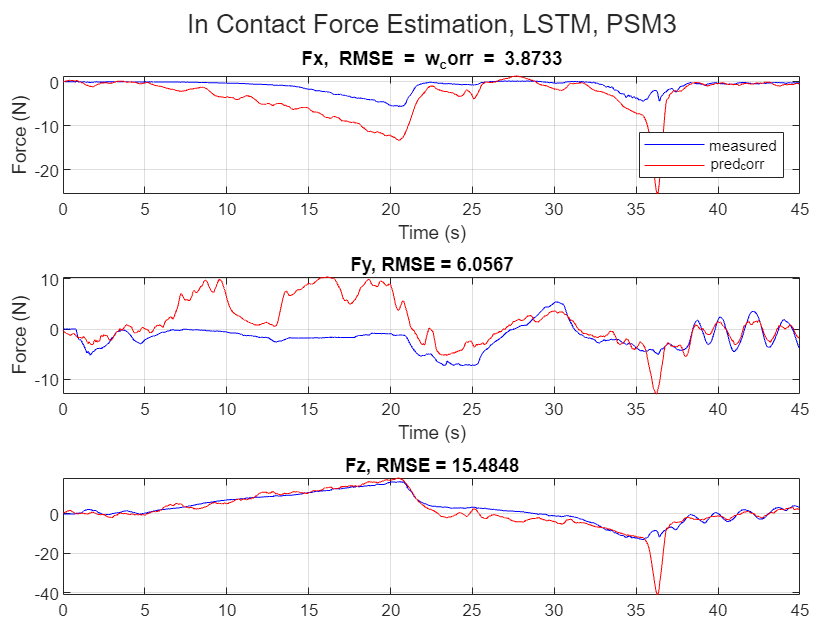


hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,2), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(joint_data(1:length(real_force)), fs_force(:,2), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
grid on
hold off

nexttile
plot(joint_data(1:length(real_force)), real_force(:,3), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(joint_data(1:length(real_force)), fs_force(:,3), 'r')
grid on


hold off